# Figure6: Tuning Curves

## 1. Setting up network

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures/Demo022722/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolderTC = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/SIEMt0.118_SEIMt2.028/']; % V1
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(DataFolderTC)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/']; % V1
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2';
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))
%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
%load("AllMFPixPara_Paper2TuneFig1V5D1.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all

AngleList = {'0.0','7.5','15.0','22.5'};
AngPrint = AngleList{1};
PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
Patt = PlotUse.LDEEquv;
N_HCout = 4;

TruncList = 1:0.5:2.5; % of sigma
TruncInd = 1;
cmap = colormap("jet");

clear text

## 3*.1.1. Tuning curve for all

Any Pix

% fisrt load all data
FrTunCurveRawDataAll = cell(size(AngleList));
AngleAll = zeros(size(AngleList));
for AngInd = 1:length(AngleList)
    AngPrint = AngleList{AngInd};
    AngleAll(AngInd) = str2num(AngPrint);
    FrTunCurveRawDataAll{AngInd} = ...
        load([DataFolderTC sprintf('FrTuneCurE_Ang%s_CosAll.mat',AngPrint)],'FrTunCurAllPix');
end

clearThree categories of pixels

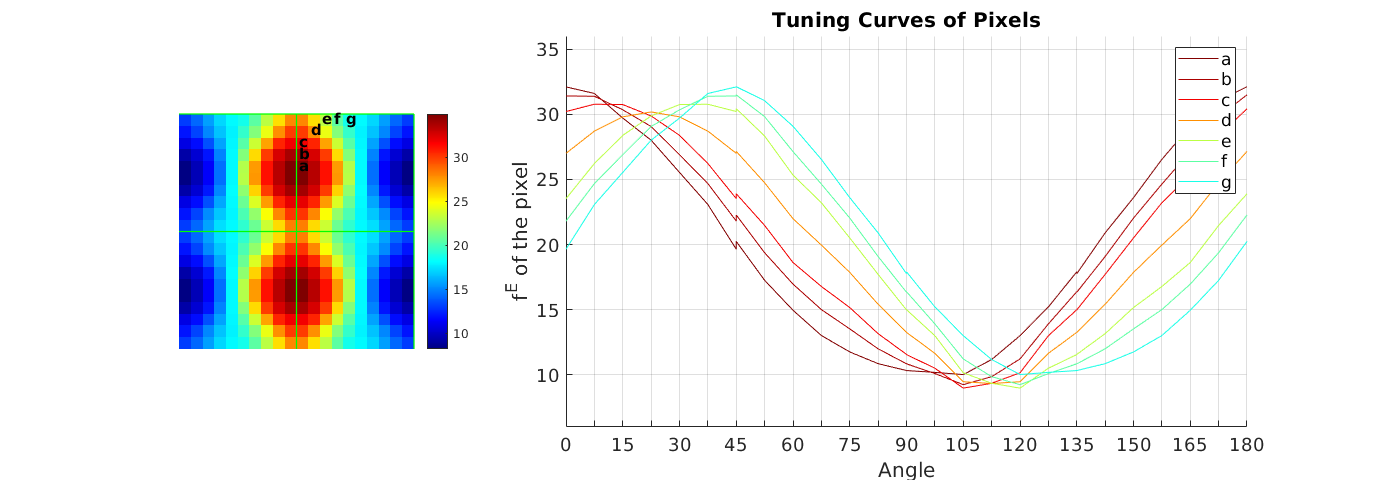

[xAll,yAll] = meshgrid(1:10,1:10);
PixCtgr = cell(1,1);
xC = NPixX*.5+0.5; yC = NPixY*.5+0.5;% center
% get pix index for each categories
[PixCtgr{1}(:,1),PixCtgr{1}(:,2),~] = ...
    find( ...
    ( max(abs(xAll-xC),abs(yAll-yC)) == 4.5...%)); ...
    & max(abs(xAll-1), abs(yAll-1))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-1), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-1))>=2));
PixCtgr{1} = [
    PixCtgr{1};
    2,2;
    2,9;
    9,2;
    9,9];

% Do the 2*2 HC and print pixel texts
Fig6 = figure('Name','TuningCurves','units','normalized','outerposition',[0,0,0.28,0.25]);
subplot(1,3,1)
EPatt = Patt.S*(1-CplxR) + Patt.C*CplxR;
ShowField(EPatt, 1:NPixY*NPixX*N_HCout^2,NPixY*N_HCout,NPixX*N_HCout)
axis([.5 2*NPixX+.5 .5 2*NPixY+.5])
axis off

hold on
CtgrPix = PixCtgr{1};
CtgrPix(CtgrPix(:,1)>5 | CtgrPix(:,2)<=5,:) = [];
[~,a] = sort(CtgrPix(:,1)+CtgrPix(:,2));
CtgrPix = CtgrPix(a,:);
PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel

% get colors of the corresponding pixels
minv = min(EPatt);
maxv = max(EPatt);
ncol = size(cmap,1);
AllCs = round(1+(ncol-1)*(EPatt-minv)/(maxv-minv));

for PixInd = 1:length(CtgrPix)
    x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
    subplot(1,3,1)
    hold on
    text(x+NPixX-0.3, y+NPixY+0.1, PixTxt(PixInd),'FontSize',11,'FontWeight','bold')
    
    % get tuning curves
    [AnglePlot,TuningCurveTrunc,~,PreferAng] = TuningCurve(...
        TruncList,AngleList,FrTunCurveRawDataAll,...
        x,y,AngleAll,NPixX,NPixY,cmap);
    AngleCenter = PreferAng*180;
    
    
    subplot(1,3,[2,3])
    hold on
    TunCurColor = cmap(AllCs(y+NPixY + (x+NPixX-1)*NPixY*N_HCout),:);
    plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd)*0.7 + ...
        TuningCurveTrunc.C(:,TruncInd)*0.3,...
        'Color',TunCurColor,'DisplayName',PixTxt(PixInd))

end

% set appropirate xticks and others
xtickAng = unique(AnglePlot);
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,2) == 1
        xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

subplot(1,3,[2,3])
xlabel('Angle'); ylabel('f^E of the pixel')
title('Tuning Curves of Pixels')

ylim([6 36]); xlim([0 180])
set(gca,'xtick',unique(AnglePlot),'xticklabel',xtickLab)
set(gca, 'FontSize',14)
grid on
xlim([min(xtickAng) max(xtickAng)])
legend

Save figures

FigName1 = sprintf('Figure6Draft');
savefig(Fig6,[FigurePaperPath FigName1 '.fig']);


Print Figs

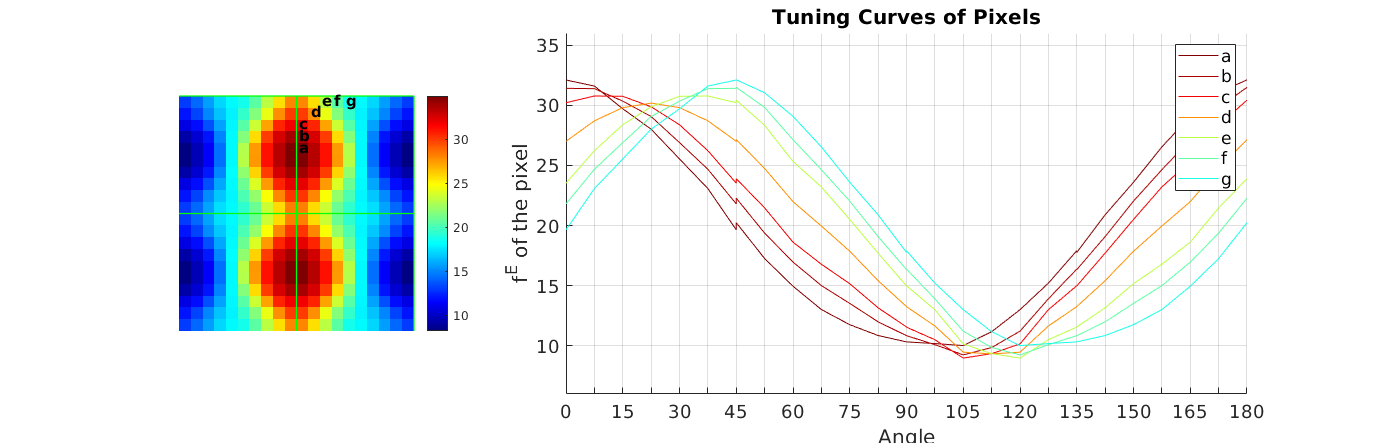

Fig6.PaperUnits = 'centimeters';
Fig6.PaperSize = [30,18];
Fig6.PaperOrientation = "landscape";
exportgraphics(Fig6,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)